First, we are going to upload the arrays and initialize all the resulting matrices.

close all;
clear;
clc;

folder_path = 'C:\Users\34651\Documents\CSIC\navidad\patientRMC'; % Folder path
file_name = 'all_spikes.mat'; % File name
full_path = fullfile(folder_path, file_name); % Combine folder path and file name

all_spikes = load(full_path); % Load the .mat file

Error using load
Unable to find file or directory 'C:\Users\34651\Documents\CSIC\navidad\patientRMC\all_spikes.mat'.

all_spikes = all_spikes.all_spikes;
Fnew = all_spikes(:,1:(size(all_spikes,2)-2),:);
all_spikes = zeros(size(Fnew,1),size(Fnew,2),size(Fnew,3));
all_spikes(:,:,:) = Fnew(:,:,:);

file_name = 'time.mat';
full_path = fullfile(folder_path, file_name);
time = load(full_path);
time = time.time;

file_name = 'all_spikes_Normal.mat';
full_path = fullfile(folder_path, file_name);
all_spikes_Normal = load(full_path);
all_spikes_Normal = all_spikes_Normal.all_spikes_Normal;
Fnew = all_spikes_Normal(:,1:(size(all_spikes_Normal,2)-2),:);
all_spikes_Normal = zeros(size(Fnew,1),size(Fnew,2),size(Fnew,3));
all_spikes_Normal(:,:,:) = Fnew(:,:,:);


file_name = 'all_morlets.mat';
full_path = fullfile(folder_path, file_name);
all_morlets = load(full_path);
all_morlets = all_morlets.all_morlets;

file_name = 'channel.mat';
full_path = fullfile(folder_path, file_name);
channel = load(full_path);
channel_labels = {channel.Channel.Name}; % array with the channels labels
% channel_new = channel_labels(:,1:(size(channel_labels,2)-107));
% channel_labels = zeros(1,length(channel_new));
% channel_labels = channel_new;
% channel_labels([1, 18, 19, 26, 27]) = [];


Fs = 512; %265 or 512
size_all_spikes = size(all_spikes); % (number of spikes, number of channels, number of samples)
number_spikes = size_all_spikes(1);

%This matrices are zeros if false ant the sample value if true
all_EoI = zeros(size(all_spikes,1),size(all_spikes,2),size(all_spikes,3));
all_HFO = zeros(size(all_spikes,1),size(all_spikes,2),size(all_spikes,3));
all_HFO_spike_region = zeros(size(all_spikes,1),size(all_spikes,2),size(all_spikes,3));

all_GFP = zeros(size(all_spikes,1),size(all_spikes,3)); 
all_start_end_spike_region = zeros(size(all_spikes,1),3); %matrix where we keep the start and end samples (indexes) of the spike region
all_start_end_HFO_within_spike = zeros(size(all_spikes,1),size(all_spikes,2),2); %matrix where we keep the beginning and end time of the HFO within the spike region
spikes_with_HFO_spike_region = zeros(1,size(all_spikes,1)); %ones if spike has HFO in the ascendent slope and zeros otherwise
channels_HFO = zeros(size(all_spikes,1),size(all_spikes,2)); %ones if a channel has HFO in the ascendent slope and zeros otherwise


Lets look for the HFO in the spike region of each channel of each spike


for z = 1:number_spikes
    morletMatrix = squeeze(all_morlets(z, :, :, :)); % Resulting size: Number of channels x Number of Samples x Number of Frequencies
    time_frequency_map = squeeze(morletMatrix(1,:,:));
    time_frequency_map = time_frequency_map'; %transpose
    frequencies = 1:1:size(all_morlets,4);

    %Creating the outputs matrices
    F = squeeze(all_spikes(z,:,:)); %matrix with the channels and sample values of spike z
    EoI = zeros(size_all_spikes(2),size_all_spikes(3));
    HFO = zeros(size_all_spikes(2),size_all_spikes(3));

    for i = 1:size_all_spikes(2)
        channel = F(i,:); 
        EoI(i,:) = determineEoI(channel,time); %EoI = event of interes of all the channels of spike z (Number of channels x Number of Samples)
    end

    all_EoI(z,:,:) = EoI;

    %Determine whether all the EoI is a HFO or not
    HFOrow = zeros(1,size_all_spikes(3));
     for j = 1:(size_all_spikes(2))
        time_frequency_map2 = squeeze(morletMatrix(j,:,:));
        time_frequency_map2 = time_frequency_map2';
        EoIrow = EoI(j,:);
        channel = F(j,:);
        %fprintf('Spike %d channles %d\n',z,j);
        [HFOrow] = determineHFOfromEoI(channel,EoIrow,Fs,time,HFOrow,time_frequency_map2);
        for a = 1:length(HFOrow)
            HFO(j,a) = HFOrow(a);
        end
        HFOrow = zeros(1,size_all_spikes(3));
     end

    all_HFO(z,:,:) = HFO;
    all_HFO(32,:,:) = 0;
    all_HFO(39,:,:) = 0;
    all_HFO(41,:,:) = 0;
    all_HFO(48,:,:) = 0;
    all_HFO(49,:,:) = 0;
    all_HFO(51,:,:) = 0;
    %Determine the HFO in spike region
    FNormal = squeeze(all_spikes_Normal(z,:,:));
    timeNormal = time;

    %Function for computing GFP and the ascending slope
    [GFP,minimum_index,spike_index, min_after_spike] = computeGFPandSpikeRegion(FNormal,timeNormal);
    all_GFP(z,:) = GFP;
    all_start_end_spike_region(z,1) = minimum_index;
    all_start_end_spike_region(z,2) = min_after_spike;
    all_start_end_spike_region(z,3) = spike_index;
    sizeF = size(F); % Number of Channels x Number of Samples
    HFO_spike_region = zeros(sizeF(1),sizeF(2));  
    for i = 1:size(F,1) %number of channels
        [HFO_spike_region_row,yes_HFO,start_HFO,end_HFO] = determineHFOinSpikeRegion(HFO(i,:),time, minimum_index, min_after_spike);
        HFO_spike_region(i,:) = HFO_spike_region_row;
        channels_HFO(z,i) = yes_HFO;
        all_start_end_HFO_within_spike(z,i,1) = start_HFO;
        all_start_end_HFO_within_spike(z,i,2) = end_HFO;
        %fprintf('\nspike: %d channel: %d HFO: %d', z, i, channels_HFO(i));
    end
    
    all_HFO_spike_region(z,:,:) = HFO_spike_region;
    
    n = 1;
    m = 0;
    while n<=size(channels_HFO,2) && m==0 %size(channels_HFO,2) = number of channels
        if channels_HFO(z,n) == 1
            spikes_with_HFO_spike_region(z) = 1;
            m = 1;
        else
            n = n+1;
        end
    end
    spikes_with_HFO_spike_region(32) = 0;
    spikes_with_HFO_spike_region(39) = 0;
    spikes_with_HFO_spike_region(41) = 0;
    spikes_with_HFO_spike_region(48) = 0;
    spikes_with_HFO_spike_region(49) = 0;
    spikes_with_HFO_spike_region(51) = 0;
end


%To keep the times where the spike region start and end only for those
%spikes that have HFO
all_start_end_spike_region_time = zeros((size(all_spikes,1)),2);
for i = 1:length(spikes_with_HFO_spike_region)
     if spikes_with_HFO_spike_region(i) == 1
         all_start_end_spike_region_time(i,1) = time(all_start_end_spike_region(i,1));
         all_start_end_spike_region_time(i,2) = time(all_start_end_spike_region(i,2));
     end
end


To discard the HFO within the spike region that start and end in the same time point.


for i = 1:length(spikes_with_HFO_spike_region)
    if (spikes_with_HFO_spike_region(i) == 1)
        for j = 1:size(channels_HFO,2)
            if channels_HFO(i,j) == 1
                if all_start_end_HFO_within_spike(i,j,1) == all_start_end_HFO_within_spike(i,j,2) || abs(all_start_end_HFO_within_spike(i,j,1) - all_start_end_HFO_within_spike(i,j,2))<0.01
                    channels_HFO(i,j) = 0;
                    if channels_HFO(i,:) == 0
                        spikes_with_HFO_spike_region(i) = 0;
                    end
                end
            end
        end
    end   
end

cont_idx = find(spikes_with_HFO_spike_region == 1);
cont_spikes = length(cont_idx); % Number of pkikes with HFO in the spike region

Print Results in the Command Window 

fprintf('Spikes with HFO in the ascendent slope:\n');

Spikes with HFO in the ascendent slope:


cont = 0;
for i = 1:length(spikes_with_HFO_spike_region)
    if spikes_with_HFO_spike_region(i) == 1
        cont = cont + 1;
        for j = 1:size(channels_HFO,2)
            if channels_HFO(i,j) == 1
                fprintf('Spike: %d Channel: %d\n',i,j);
            end
        end
    end
end

Spike: 14 Channel: 12
Spike: 14 Channel: 13
Spike: 40 Channel: 17
Spike: 42 Channel: 25
Spike: 43 Channel: 63
Spike: 45 Channel: 37


fprintf('\nThere are %d spikes with HFO in the spike region out of %d\n',cont,length(spikes_with_HFO_spike_region));


There are 5 spikes with HFO in the spike region out of 53


% To check if we actually have HFO in any ascendent slope of any spike
i = 1;
a = 0;
while i<=(length(spikes_with_HFO_spike_region)) && a == 0
    if spikes_with_HFO_spike_region(i) == 1
        a = 1;
    else
        i = i+1;
    end
end

if a == 0
    disp('No spikes with HFO in the ascendent slope');
end
fprintf('\n')
disp('Spikes without HFO in the ascendent slope:')

Spikes without HFO in the ascendent slope:


for i =1:length(spikes_with_HFO_spike_region)
    if spikes_with_HFO_spike_region(i) == 0
        fprintf('%d, ',i);    
    end
end

1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 15, 16, 17, 18, 19, 20, 21, 22, 23, 24, 25, 26, 27, 28, 29, 30, 31, 32, 33, 34, 35, 36, 37, 38, 39, 41, 44, 46, 47, 48, 49, 50, 51, 52, 53, 

Print in The Command Window the epochs that have HFO (spike or not spike region)

fprintf('\n\nSpikes with HFO:\n');



Spikes with HFO:


for i = 1:size(all_HFO,1)
    spike_HFO_matrix = squeeze(all_HFO(i,:,:));
    for j = 1:(size(spike_HFO_matrix,1))
        HFO_channel = spike_HFO_matrix(j,:);
        a = 0;
        k = 1;
        while k <= length(HFO_channel) && a==0
            if HFO_channel(k) ~= 0
                fprintf('Spike: %d Channel: %d\n',i,j);
                a = 1;
            else
                k = k+1;
            end
        end
    end
end

Spike: 4 Channel: 4
Spike: 9 Channel: 4
Spike: 14 Channel: 12
Spike: 14 Channel: 13
Spike: 26 Channel: 17
Spike: 29 Channel: 17
Spike: 29 Channel: 25
Spike: 31 Channel: 17
Spike: 34 Channel: 16
Spike: 34 Channel: 21
Spike: 35 Channel: 8
Spike: 35 Channel: 23
Spike: 35 Channel: 30
Spike: 35 Channel: 37
Spike: 35 Channel: 43
Spike: 36 Channel: 37
Spike: 37 Channel: 5
Spike: 37 Channel: 17
Spike: 37 Channel: 37
Spike: 40 Channel: 17
Spike: 42 Channel: 25
Spike: 43 Channel: 17
Spike: 43 Channel: 63
Spike: 44 Channel: 23
Spike: 44 Channel: 37
Spike: 45 Channel: 16
Spike: 45 Channel: 17
Spike: 45 Channel: 37
Spike: 47 Channel: 17
Spike: 50 Channel: 17
Spike: 52 Channel: 17
Spike: 52 Channel: 34
Spike: 53 Channel: 17


## Plots

Select the Spike and channel Number you want to plot in Matlab.

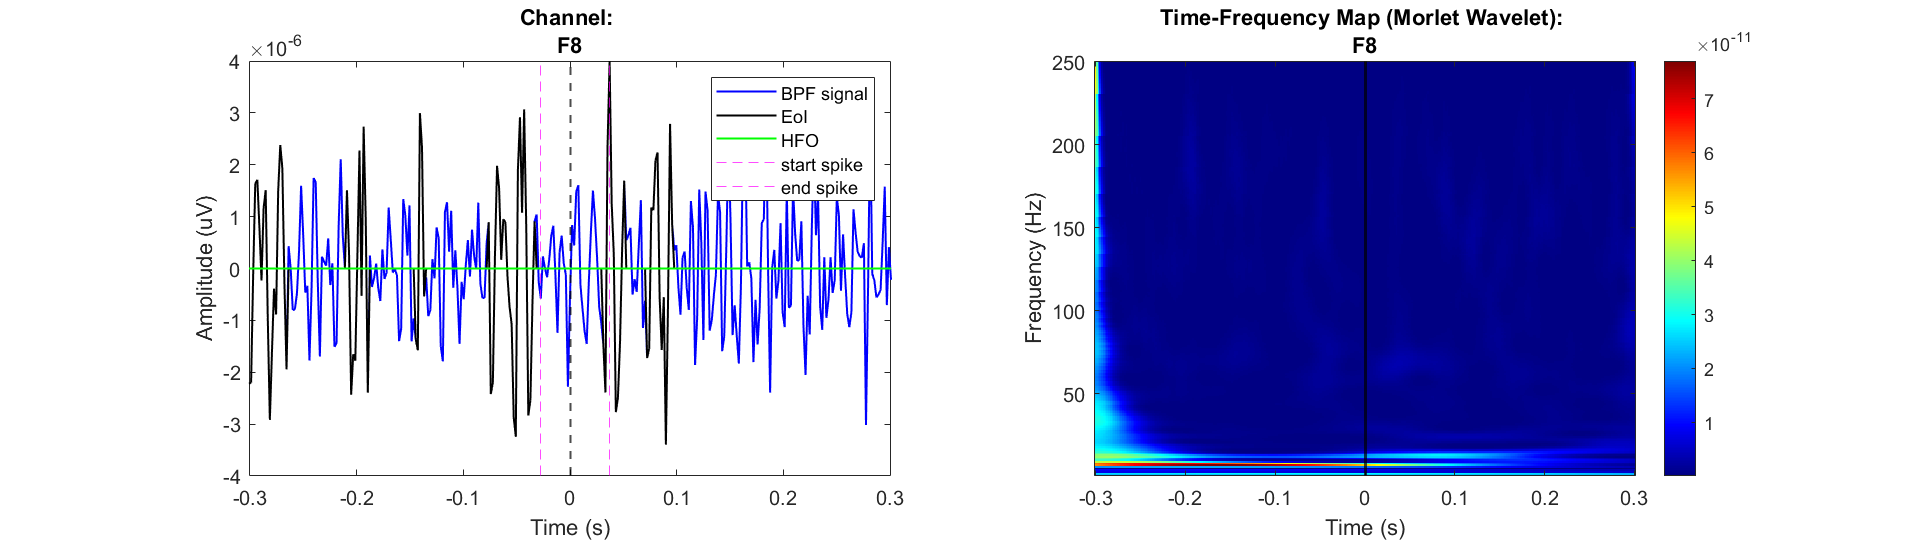

close all;
spike_number = 1;
spike_plot = squeeze(all_spikes(spike_number,:,:));
spike_EoI = squeeze(all_EoI(spike_number,:,:));
spike_HFO = squeeze(all_HFO(spike_number,:,:));
spike_morlet = squeeze(all_morlets(spike_number,:,:,:));
spike_Normal_plot = squeeze(all_spikes_Normal(spike_number,:,:));
GFP_plot = squeeze(all_GFP(spike_number,:));

channel_number = 22;
channel_plot = spike_plot(channel_number,:);
EoI_plot = spike_EoI(channel_number,:);
HFO_plot = spike_HFO(channel_number,:);
morlet_plot = squeeze(spike_morlet(channel_number,:,:));
morlet_plot = morlet_plot';

start = time(all_start_end_spike_region(spike_number,1));
finish = time(all_start_end_spike_region(spike_number,2));

spike_Normal_plot_new = zeros(size(all_spikes_Normal,2)-2,size(all_spikes_Normal,3));
for i = 1:(size(all_spikes_Normal,2)-2)
    for j = 1:size(all_spikes_Normal,2)
        spike_Normal_plot_new(i,j) = spike_Normal_plot(i,j);
    end
end
        
screen_size = get(0,'ScreenSize'); %[left,bottom,width,height]
figure_width = screen_size(3);  
figure_height = screen_size(4) / 2; 
left = 0; 
bottom = screen_size(4) / 2;

figure(1)
set(gcf, 'Position', [left, bottom, figure_width, figure_height]);
subplot(1,2,1)
plot(time,channel_plot,'b','LineWidth',1);
hold on
plot(time,EoI_plot,'k','LineWidth',1);
hold on
plot(time,HFO_plot,'g','LineWidth',1);
hold on
xline(start,'m--','LineWidt',0.5);
hold on
xline(finish,'m--','LineWidt',0.5);
if finish ~= 0
    hold on
    xline(0,'k--','LineWidth',1);
end
xlim([min(time) max(time)]);
xlabel('Time (s)');
ylabel('Amplitude (uV)');
legend('BPF signal','EoI','HFO','start spike','end spike');
title(['Channel: ',channel_labels(channel_number)]);

subplot(1,2,2)
imagesc(time, frequencies, morlet_plot);
hold on
xline(0,'k','LineWidth',1.5);
set(gca, 'YDir', 'normal'); % Ensure frequency axis is increasing upward
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title(['Time-Frequency Map (Morlet Wavelet): ',channel_labels(channel_number)]);
colorbar;
colormap('jet');
hold off

%close all;

## Create results pdf

Define the folder and filename for the PDF report

%folder_path = fullfile(getenv('USERPROFILE'), 'Documents\CSIC\navidad\patientMCC\arraysFT7'); % Windows
pdf_filename = fullfile(folder_path, 'HFO_Report.pdf');

% Si el archivo PDF ya existe, eliminarlo
if exist(pdf_filename, 'file') == 2
   delete(pdf_filename);
end

% Open PDF file
import mlreportgen.dom.*;
import mlreportgen.report.*;

% Create a PDF document
report = Document(pdf_filename, 'pdf');

% Add a title to the report
append(report, Paragraph('HFO Report in Ascending Slope'));
append(report, Paragraph(' '));

% Table initialization
num_spikes = size(channels_HFO, 1);

% Find spikes with HFO in ascending slope
spikes_with_HFO = find(spikes_with_HFO_spike_region);
channels_with_HFO = cell(length(spikes_with_HFO), 1);

if cont_spikes ~= 0
    for i = 1:length(spikes_with_HFO)
        spike_idx = spikes_with_HFO(i);
        channels_with_HFO{i} = find(channels_HFO(spike_idx, :) > 0);
    end
    
    % Create a table for spikes and their corresponding channels with HFO
    table_data = {'Spike', 'Channel',' Name','Start Slope','End Slope', 'Start HFO', 'End HFO'};
    for i = 1:length(spikes_with_HFO)
        spike_idx = spikes_with_HFO(i);
        start_time = num2str(all_start_end_spike_region_time(spike_idx, 1));
        end_time = num2str(all_start_end_spike_region_time(spike_idx, 2));
    
        % Get channels with HFO for this spike
        channels_idx = find(channels_HFO(spike_idx, :) > 0);
    
        for j = 1:length(channels_idx)
            ch_num = channels_idx(j);
            ch_name = channel_labels{ch_num};  % Access the name from the channels array
            start_time_HFO = num2str(all_start_end_HFO_within_spike(spike_idx,channels_idx(j),1));
            end_time_HFO = num2str(all_start_end_HFO_within_spike(spike_idx,channels_idx(j),2));
            % Add one row per (spike, channel) pair
            table_data = [table_data; ...
                {num2str(spike_idx), num2str(ch_num), ch_name, start_time, end_time,start_time_HFO,end_time_HFO}];
        end
    end


    % Convert cell array to DOM table
    t = Table(table_data);
    t.Style = {Width('100%'), Border('solid')};
    append(report, t);
    append(report, Paragraph(' '));
end

% Summary section
summary_text = sprintf('%d out of %d spikes have HFO oscillations in the ascending slope.', cont_spikes, num_spikes);
append(report, Paragraph(summary_text));

% Spikes without HFO in the ascending slope
spikes_without_HFO = setdiff(1:num_spikes, spikes_with_HFO);
spikes_without_HFO_text = sprintf('Spikes without HFO in the ascending slope: %s', num2str(spikes_without_HFO));
append(report, Paragraph(spikes_without_HFO_text));




% Close the report
close(report);
disp(['Report saved to ', pdf_filename]);

Report saved to C:\Users\34651\Documents\CSIC\navidad\patientRMC\HFO_Report.pdf


Lets create the table for Latex

% Define folder and LaTeX filename
%folder_path = fullfile(getenv('USERPROFILE'), '\Documents\CSIC\navidad\patientMCC\arraysFT7'); % Windows
latex_filename = fullfile(folder_path, 'HFO_Report_Table_Latex.tex');



% Open file for writing
fid = fopen(latex_filename, 'w');

% Write LaTeX table header
fprintf(fid, '\\begin{table}[H]\n');
fprintf(fid, '\\centering\n');
fprintf(fid, '\\footnotesize\n');
fprintf(fid, '\\begin{tabular}{|c|c|c|c|c|c|c|}\n');
fprintf(fid, '\\hline\n');
fprintf(fid, 'Spike & Channel & Name & Start Slope(s) & End Slope(s) & Start HFO(s) & End HFO(s) \\\\\n');
fprintf(fid, '\\hline\n');

% Fill table with data
spikes_with_HFO = find(spikes_with_HFO_spike_region);
if cont_spikes ~= 0
    for i = 1:length(spikes_with_HFO)
        spike_idx = spikes_with_HFO(i);
        start_time = all_start_end_spike_region_time(spike_idx, 1);
        end_time = all_start_end_spike_region_time(spike_idx, 2);
    
        channels_idx = find(channels_HFO(spike_idx, :) > 0);
    
        for j = 1:length(channels_idx)
            ch_num = channels_idx(j);
            ch_name = channel_labels{ch_num};
            start_HFO = all_start_end_HFO_within_spike(spike_idx, ch_num, 1);
            end_HFO   = all_start_end_HFO_within_spike(spike_idx, ch_num, 2);
    
            % Escape underscores in channel names for LaTeX
            ch_name = strrep(ch_name, '_', '\_');
    
            % Write the table row
            fprintf(fid, '%d & %d & %s & $%.3e$ & $%.3e$ & $%.3e$ & $%.3e$ \\\\\n', ...
                    spike_idx, ch_num, ch_name, start_time, end_time, start_HFO, end_HFO);
        end
    end
end

% Close table
fprintf(fid, '\\hline\n');
fprintf(fid, '\\end{tabular}\n');
fprintf(fid, '\\caption{HFO co-occured with Spikes}\n');
fprintf(fid, '\\end{table}\n');

fclose(fid);
disp(['LaTeX table saved to ', latex_filename]);

LaTeX table saved to C:\Users\34651\Documents\CSIC\navidad\patientRMC\HFO_Report_Table_Latex.tex


## Generate folder with the figures for spikes with HFO

Define la carpeta donde se guardarán las figuras

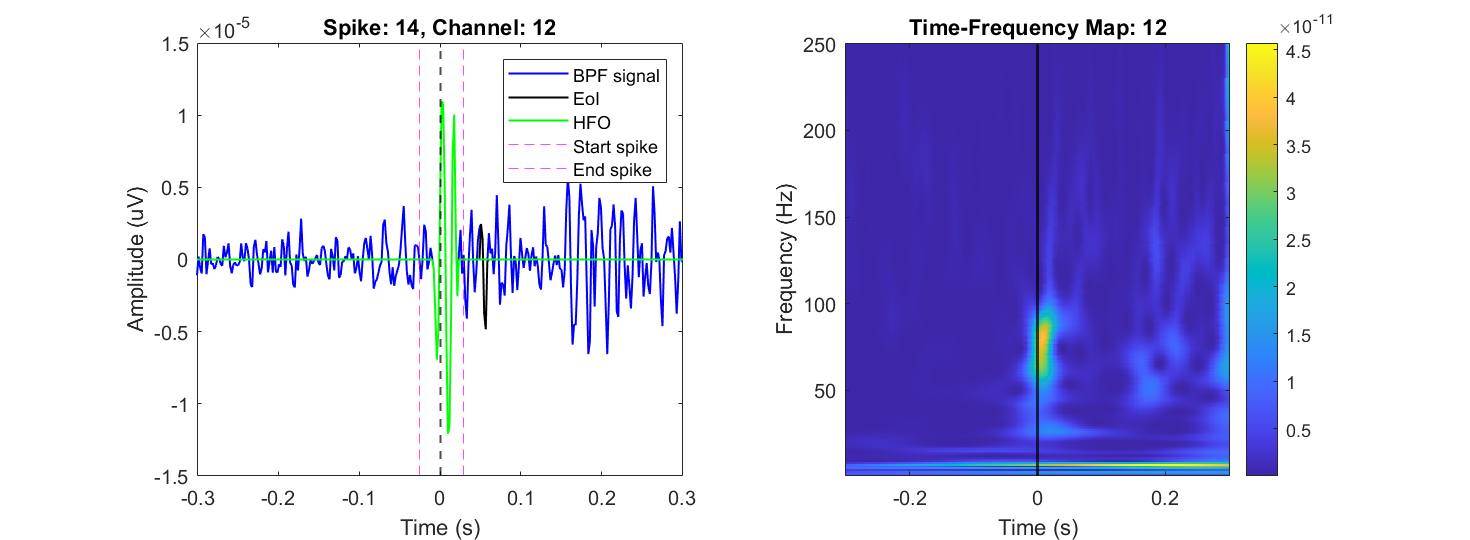

Figura guardada: C:\Users\34651\Documents\CSIC\navidad\patientRMC\Figures\Spike_14_Channel_12.png


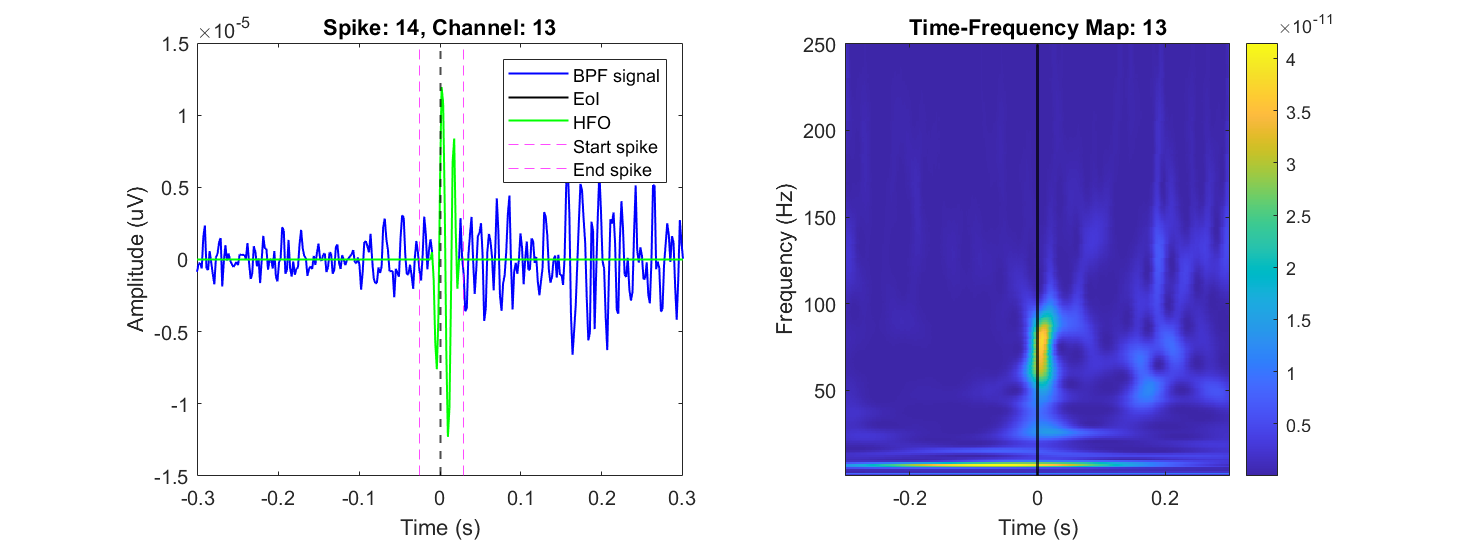

Figura guardada: C:\Users\34651\Documents\CSIC\navidad\patientRMC\Figures\Spike_14_Channel_13.png


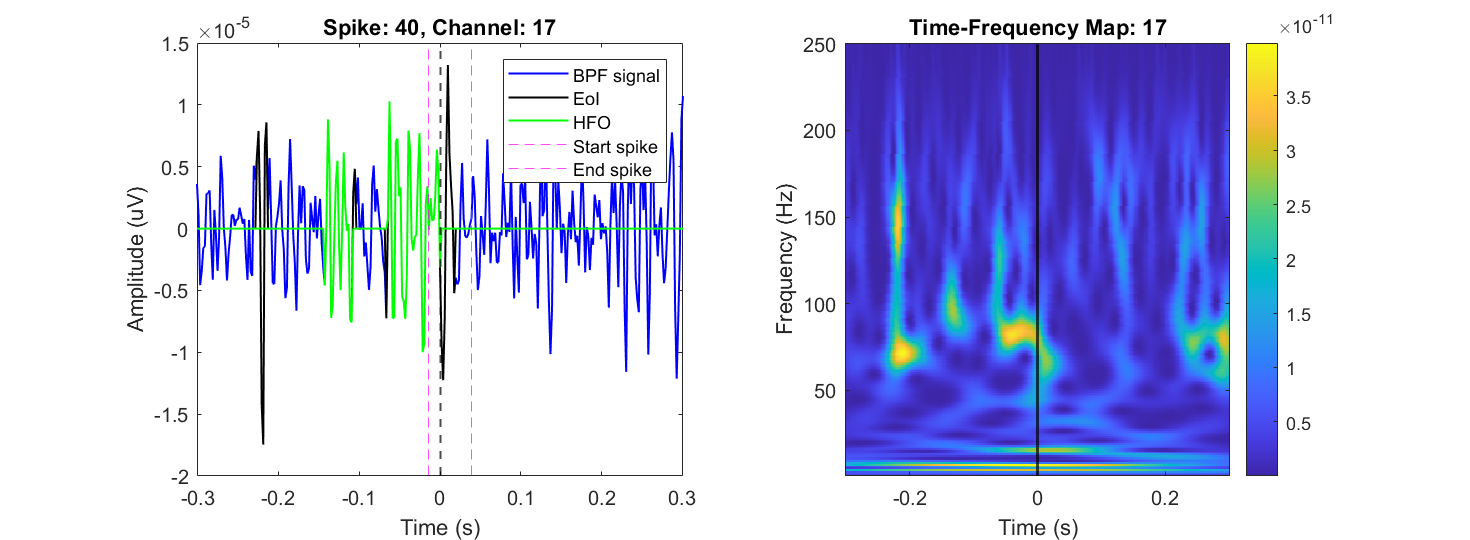

Figura guardada: C:\Users\34651\Documents\CSIC\navidad\patientRMC\Figures\Spike_40_Channel_17.png


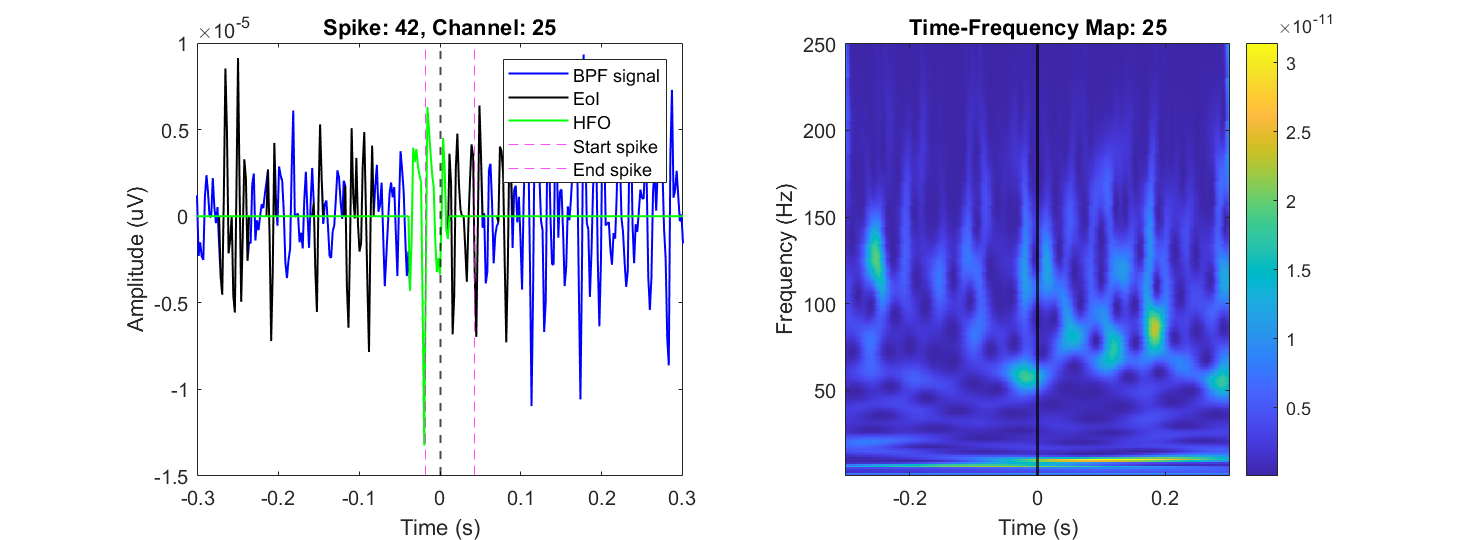

Figura guardada: C:\Users\34651\Documents\CSIC\navidad\patientRMC\Figures\Spike_42_Channel_25.png


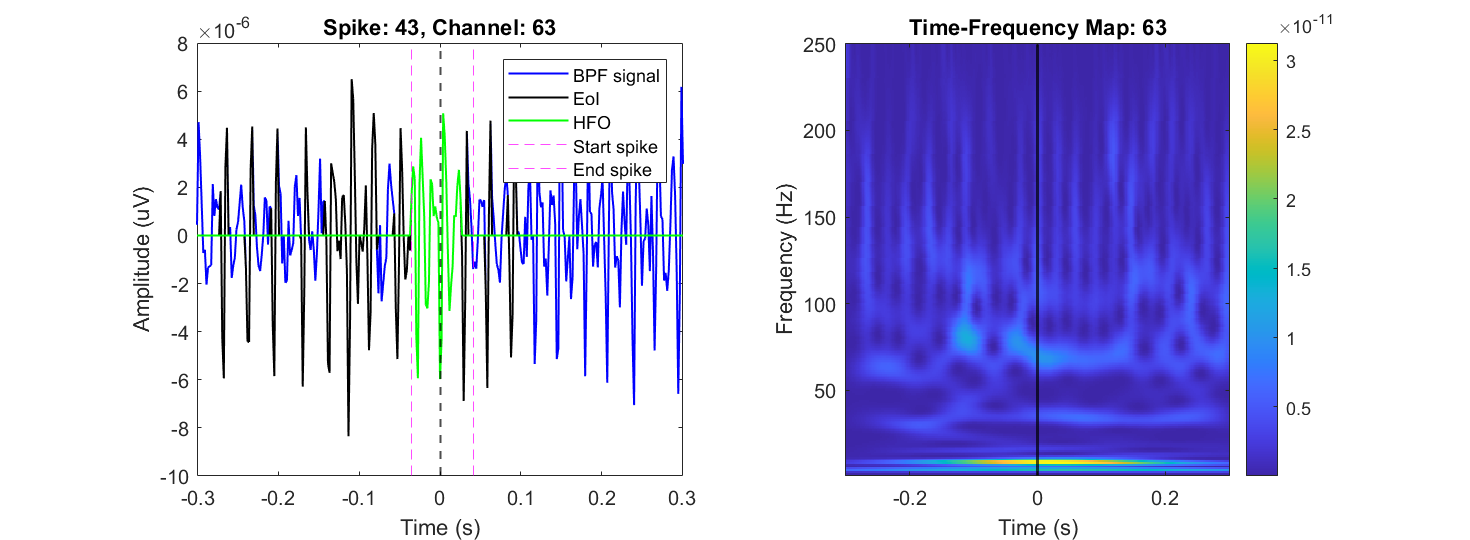

Figura guardada: C:\Users\34651\Documents\CSIC\navidad\patientRMC\Figures\Spike_43_Channel_63.png


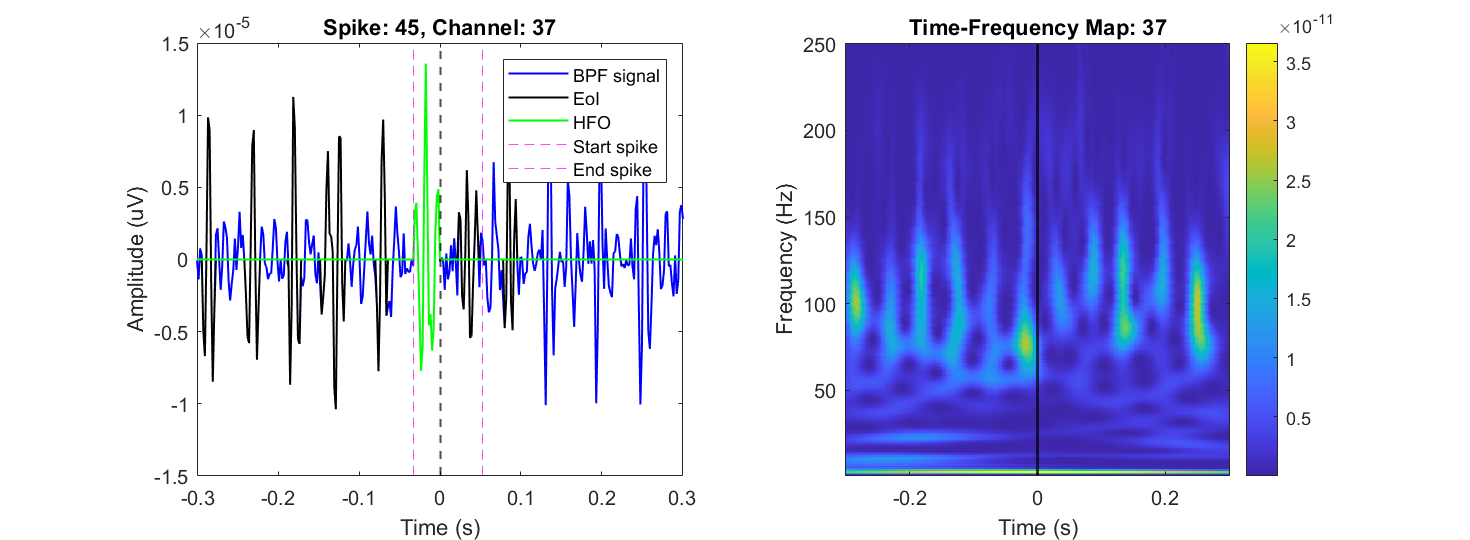

Figura guardada: C:\Users\34651\Documents\CSIC\navidad\patientRMC\Figures\Spike_45_Channel_37.png


output_folder =  ('C:\Users\34651\Documents\CSIC\navidad\patientRMC\Figures'); % Cambia esta ruta si es necesario

% Check if the folder exists
if exist(output_folder, 'dir')
    % Delete all files in the folder
    delete(fullfile(output_folder, '*'));
else
    % Create the folder if it does not exist
    mkdir(output_folder);
end

% Generar y guardar las figuras como PNG
for i = 1:length(spikes_with_HFO)
    spike_number = spikes_with_HFO(i);
    spike_plot = squeeze(all_spikes(spike_number,:,:));
    spike_EoI = squeeze(all_EoI(spike_number,:,:));
    spike_HFO = squeeze(all_HFO(spike_number,:,:));
    spike_morlet = squeeze(all_morlets(spike_number,:,:,:));

    for j = 1:length(channels_with_HFO{i})
        channel_number = channels_with_HFO{i}(j);

        channel_plot = spike_plot(channel_number,:);
        EoI_plot = spike_EoI(channel_number,:);
        HFO_plot = spike_HFO(channel_number,:);
        morlet_plot = squeeze(spike_morlet(channel_number,:,:))';

        start = time(all_start_end_spike_region(spike_number,1));
        finish = time(all_start_end_spike_region(spike_number,2));

        % Crear figura
        figure('Position', [100, 100, 980, 360]); % Ajustar tamaño de la figura

        % Subplot para la señal
        subplot(1, 2, 1);
        plot(time, channel_plot, 'b', 'LineWidth', 1);
        hold on;
        plot(time, EoI_plot, 'k', 'LineWidth', 1);
        plot(time, HFO_plot, 'g', 'LineWidth', 1);
        xline(start, 'm--', 'LineWidth', 0.5);
        xline(finish, 'm--', 'LineWidth', 0.5);
        if finish ~= 0
            xline(0, 'k--', 'LineWidth', 1);
        end
        xlim([min(time), max(time)]);
        xlabel('Time (s)');
        ylabel('Amplitude (uV)');
        legend('BPF signal', 'EoI', 'HFO', 'Start spike', 'End spike');
        title(['Spike: ', num2str(spike_number), ', Channel: ', num2str(channel_number)]);

        % Subplot para el mapa tiempo-frecuencia
        subplot(1, 2, 2);
        imagesc(time, frequencies, morlet_plot);
        hold on;
        xline(0, 'k', 'LineWidth', 1.5);
        set(gca, 'YDir', 'normal');
        xlabel('Time (s)');
        ylabel('Frequency (Hz)');
        title(['Time-Frequency Map: ', num2str(channel_number)]);
        colorbar;

        % Ajustar márgenes
        set(gca, 'LooseInset', max(get(gca, 'TightInset'), 0.02));

        % Guardar figura como PNG
        fig_filename = fullfile(output_folder, sprintf('Spike_%d_Channel_%d.png', spike_number, channel_number));
        print(gcf, fig_filename, '-dpng', '-r300'); % Resolución de 300 DPI
        close(gcf);

        disp(['Figura guardada: ', fig_filename]);
    end
end


disp(['Todas las figuras se han guardado en: ', output_folder]);

Todas las figuras se han guardado en: C:\Users\34651\Documents\CSIC\navidad\patientRMC\Figures


## **Generate folder with the figures for the GFP and Spikes Regions**

Define la carpeta donde se guardarán las figuras

output_folder = ('C:\Users\34651\Documents\CSIC\navidad\patientRMC\Figures_GFP'); % Cambia esta ruta si es necesario

% Check if the folder exists
if exist(output_folder, 'dir')
    % Delete all files in the folder
    delete(fullfile(output_folder, '*'));
else
    % Create the folder if it does not exist
    mkdir(output_folder);
end

% === Loop through spikes with HFO ===
[num_spikes, num_channels, num_samples] = size(all_spikes);

for i = 1:num_spikes
    % Check if this spike has HFO (i.e. any channel has a 1)
    if any(channels_HFO(i, :))
        % Extract EEG data for this spike
        epoch = squeeze(all_spikes_Normal(i, :, :));  % 29 x 309
        gfp = squeeze(all_GFP(i, :));              % 1 x 309

        % Ascending slope indices (sample numbers)
        slope_start_idx = all_start_end_spike_region(i, 1);
        slope_end_idx = all_start_end_spike_region(i, 2);

        % === Start figure ===
        figure('Visible', 'off');  % set to 'on' to show while running

        % Plot all channels in black
        h_channels = plot(time, epoch, 'k','LineWidth',0.5); hold on;

        % Plot GFP in green (offset above signals for clarity)
        h_gfp = plot(time, gfp, 'g', 'LineWidth', 1);

        % Plot ascending slope of GFP in red
        if slope_start_idx > 0 && slope_end_idx > 0
            time_slope = time(slope_start_idx:slope_end_idx);
            gfp_slope = gfp(slope_start_idx:slope_end_idx);
            h_slope = plot(time_slope, gfp_slope, 'r', 'LineWidth', 1);
        end

        title(['Spike ', num2str(i), ' with HFO']);
        xlabel('Time (s)');
        ylabel('Amplitude (\muV)');
        xlim([time(1) time(length(time))]);
        
        
        % Build legend with handles, skipping invalid slope if necessary
        if isgraphics(h_slope)
            legend([h_channels(1), h_gfp, h_slope], {'EEG Channels', 'GFP', 'GFP Spike'});
        else
            legend([h_channels(1), h_gfp], {'EEG Channels', 'GFP'});
        end
        % Save the figure
        filename = fullfile(output_folder, ['Spike_' num2str(i) '_GFP.png']);
        saveas(gcf, filename);
        close(gcf);  % Close to save memory
    end
end

disp(['Plots saved in: ', output_folder]);

Plots saved in: C:\Users\34651\Documents\CSIC\navidad\patientRMC\Figures_GFP


Lets look for the SOZ

% Set your data folder
folder_path_db = 'C:\Users\34651\Documents\brainstorm_originalRecordings\RMC\data\RMC\Spike_normal';
files = dir(fullfile(folder_path_db, '*.mat'));

sCortex = load('C:\Users\34651\Documents\brainstorm_originalRecordings\RMC\anat\RMC\tess_cortex_pial_low.mat');
vertices = sCortex.Vertices; %Nx3, 3D positions of all the vertices

% Initialize container
sources = {};
k = 1;

% Load only Brainstorm source files
for i = 1:length(files)
    full_path = fullfile(files(i).folder, files(i).name);
    temp = load(full_path);

    if isfield(temp, 'ImageGridAmp')
        sources{k} = temp;
        k = k + 1;
    end
end

% Separate cMEM and wMEM
cMEM_sources = {};
wMEM_sources = {};

HFO_maps = {};
spike_maps = {};

HFO_sources_intensities = {};
spike_sources_intensities = {};

for i = 1:length(sources)
    s = sources{i};
    if strcmp(s.Function, 'cMEM')
        cMEM_sources{end+1} = s;
    elseif strcmp(s.Function, 'wMEM')
        wMEM_sources{end+1} = s;
    end
end
sCortex.Atlas(end+1).Name = 'SOZ_HFO';
sCortex.Atlas(end+1).Name = 'SOZ_spike';
a = 1;
for i = 1:length(spikes_with_HFO_spike_region)
    if (spikes_with_HFO_spike_region(i)==1)
        for j = 1:size(channels_HFO,2)
            if channels_HFO(i,j) == 1
                source = wMEM_sources{i};
                
                % Spatial map (sources × atoms)
                S = source.ImageGridAmp{1};

                % Temporal activation (atoms × time)
                T = source.ImageGridAmp{2};

                % Reconstructed data (sources,vertices × time)
                reconstructed = S * T; 
                
                % Example: all_time_start_end = [-0.020, 0.020];
                t_start = all_start_end_HFO_within_spike(i,j,1);
                t_end = all_start_end_HFO_within_spike(i,j,2);
                time_vec = source.Time;
                
                % Find the indices closest to start and end
                [~, i_start] = min(abs(time_vec - t_start));
                [~, i_end]   = min(abs(time_vec - t_end));
                
                reconstructed_avg = mean(reconstructed(:, i_start:i_end), 2); %one column vector because is sources at just one time
                HFO_sources_intensities{a} = reconstructed_avg;
                reconstructed_avg_norm = reconstructed_avg/max(reconstructed_avg);
                HFO_map = (reconstructed_avg_norm>=0.8); %column vector of same size wuth ones when happens and zeros otherwise
                HFO_maps{a} = HFO_map;
                a = a+1;
                
                reconstructed_avg_norm = find(reconstructed_avg_norm >= 0.8);  % idx (=vertices)>0.8
                
                % Create new scout struct
                new_scout.Vertices = reconstructed_avg_norm;              % Required
                new_scout.Seed = reconstructed_avg_norm(1);               % Pick first vertex as seed
                new_scout.Color = [1 1 1];                                % Red, or any RGB
                new_scout.Label = ['SOZ_HFO_', num2str(i), '_', num2str(j)];  % Custom label
                new_scout.Function = 'Mean';                              % Standard function
                new_scout.Region = 'LF';                                  % Optional: change as needed
                new_scout.Handles = [];                                   % Usually empty
                
                % Add to the User scouts atlas (index 1)
                sCortex.Atlas(end-1).Scouts(end+1) = new_scout;
                source.Atlas = sCortex.Atlas;
            end     
        end
    end      
end
a = 1;
for i = 1:length(spikes_with_HFO_spike_region)
    source = cMEM_sources{i};
    intensities = source.ImageGridAmp;

    t_idx = all_start_end_spike_region(i,3);  % index where t is closest to zero
 
    % Get the activity map at t = 0
    source_at_spike = source.ImageGridAmp(:, t_idx);  % [vertices × 1]
    spike_sources_intensities{a} = source_at_spike;
    source_at_spike = source_at_spike/max(source_at_spike);
    spike_map = (source_at_spike>=0.8); %column vector of same size wuth ones when happens and zeros otherwise
    spike_maps{a} = spike_map;
    a = a+1;
    source_at_spike = find(source_at_spike>=0.8);
    
    % Create new scout struct
    new_scout.Vertices = source_at_spike;              % Required
    new_scout.Seed = source_at_spike(1);               % Pick first vertex as seed
    new_scout.Color = [1 1 1];                         % Red, or any RGB
    new_scout.Label = ['SOZ_spike_', num2str(i)];      % Custom label
    new_scout.Function = 'Mean';                       % Standard function
    new_scout.Region = 'LF';                           % Optional: change as needed
    new_scout.Handles = [];                            % Usually empty
    
    sCortex.Atlas(end).Scouts(end+1) = new_scout;
    
end


matrix = cell2mat(spike_maps);  % Convert to 15002x100 matrix
sum_vector = sum(matrix, 2); 
sum_vector = sum_vector/size(matrix,2);
conceus_scout_spike = find(sum_vector>0.2);

matrix = cell2mat(HFO_maps);  % Convert to 15002x100 matrix
sum_vector = sum(matrix, 2); 
sum_vector = sum_vector/size(matrix,2);
conceus_scout_HFO = find(sum_vector>0.2);

if size(conceus_scout_spike,1)==0
    conceus_scout(1).Vertices = [];
    conceus_scout(1).Seed = [];
else
    conceus_scout(1).Vertices = conceus_scout_spike;
    conceus_scout(1).Seed = conceus_scout_spike(1);
end

conceus_scout(1).Color = [1 1 1];                        
conceus_scout(1).Label = 'Conceus_spike';      
conceus_scout(1).Function = 'Mean';                       
conceus_scout(1).Region = 'LF';                           
conceus_scout(1).Handles = []; 

conceus_scout(2).Vertices = conceus_scout_HFO;
conceus_scout(2).Seed = conceus_scout_HFO(1);
conceus_scout(2).Color = [1 1 1];                        
conceus_scout(2).Label = 'Conceus_HFO';      
conceus_scout(2).Function = 'Mean';                       
conceus_scout(2).Region = 'LF';                           
conceus_scout(2).Handles = []; 

Lets look for the region of the brain that is closer to each SOZ determined by the HFO

% Find the index of the atlas named 'Destrieux'
idx = find(strcmp({sCortex.Atlas.Name}, 'Destrieux'));

% Check if it was found
if isempty(idx)
    error('Destrieux atlas not found in sCortex.Atlas');
else
    brain_regions = sCortex.Atlas(idx).Scouts;
end

SOZ_regions_HFO = sCortex.Atlas(end-1).Scouts;
coords = sCortex.Vertices;

num_soz = length(SOZ_regions_HFO);
num_regions = length(brain_regions);

min_distances_HFO = zeros(num_soz, 1);

SOZ_struct(num_soz) = struct('SOZ_Label', '', ...
                             'Region_Labels', {{}}, ...
                             'Region_Sides',  {{}});

for i = 1:num_soz  
    % Get SOZ coordinates
    soz_idx = SOZ_regions_HFO(i).Vertices(:);
    soz_coords = coords(soz_idx, :);
    soz_label = SOZ_regions_HFO(i).Label;
   
     region_dists = zeros(num_regions, 1);

   for j = 1:num_regions
        region_idx = brain_regions(j).Vertices(:);
        region_coords = coords(region_idx, :);

        % Compute pairwise distances
        D = pdist2(soz_coords, region_coords);  % [n_soz x n_region]
        Dzeros = find(D==0);
        % Save the min distance to this region
        region_dists(j) = min(D(:));
        
   end
   % Get brain regions that overlap (distance == 0)
    match_idx = find(region_dists == 0);
    matched_labels = {brain_regions(match_idx).Label};
    matched_regions = {brain_regions(match_idx).Region};

    % Fill in the struct
    SOZ_struct(i).SOZ_Label = soz_label;
    SOZ_struct(i).Region_Labels = matched_labels;
    SOZ_struct(i).Region_Sides  = matched_regions;
    sCortex.Atlas(end-1).Scouts(i).Region = matched_regions(1);

end



Count 

% Initialize maps for both Region_Label and Generic_Region
region_counts = containers.Map();


for i = 1:length(SOZ_struct)
    % --- Count Region_Label ---
    region_labels = SOZ_struct(i).Region_Labels;
    for j = 1:length(region_labels)
        label = region_labels{j};
        if isKey(region_counts, label)
            region_counts(label) = region_counts(label) + 1;
        else
            region_counts(label) = 1;
        end
    end
end

%% Convert maps to tables for nicer display and plotting
% Region_Label
region_keys = keys(region_counts);
region_values = values(region_counts);
region_table_HFO = table(region_keys', cell2mat(region_values)', 'VariableNames', {'Region', 'Count'});
region_table_HFO = sortrows(region_table_HFO, 'Count', 'descend');


%% Show the tables in Live Script
disp('🧠 Region_Label Counts:');

🧠 Region_Label Counts:


disp(region_table_HFO);

                Region                Count
    ______________________________    _____

    {'G_temp_sup-Lateral L'      }      4  
    {'Pole_temporal L'           }      4  
    {'G_temporal_middle L'       }      2  
    {'S_orbital-H_Shaped L'      }      2  
    {'S_temporal_inf L'          }      2  
    {'S_temporal_sup L'          }      2  
    {'G_occipital_middle R'      }      1  
    {'G_occipital_sup R'         }      1  
    {'S_oc_sup_and_transversal R'}      1  
    {'S_parieto_occipital R'     }      1  



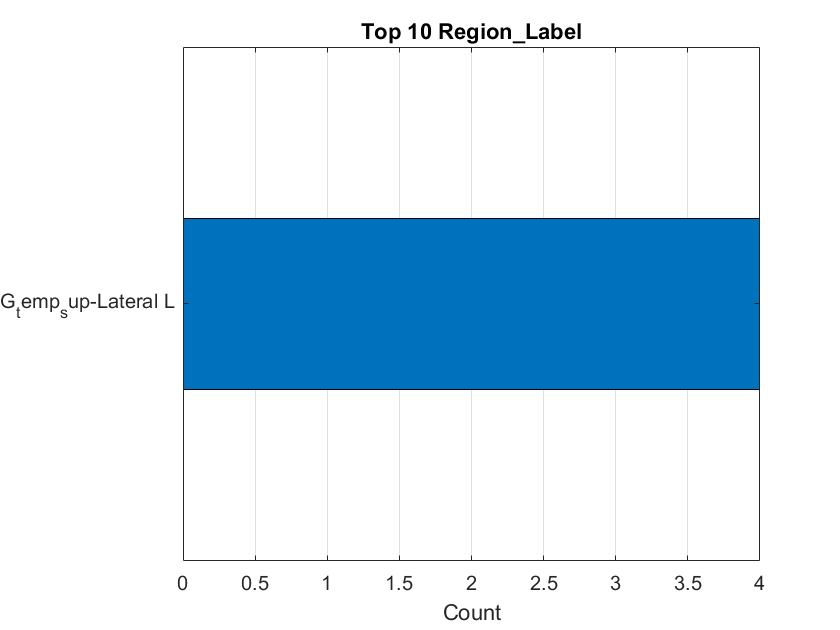

% Set full file path
filename = fullfile(folder_path, "region_table_HFO.txt");

% Write the table to CSV
writetable(region_table_HFO, filename);

%% Plotting the top 10 from each category
figure;
barh(region_table_HFO.Count(1));
set(gca, 'yticklabel', region_table_HFO.Region(1));
xlabel('Count');
title('Top 10 Region\_Label');
grid on;

Latex table with the results


% Define folder and LaTeX filename
%folder_path = fullfile(getenv('USERPROFILE'), 'Documents\CSIC\navidad\patientMCC\arraysFT7'); % Windows
latex_filename = fullfile(folder_path, 'SOZ_HFO_Latex.tex');

% Open file for writing
fid = fopen(latex_filename, 'w');

% Write LaTeX table header
fprintf(fid, '\\begin{longtable}{|c|c|c|p{6cm}|}\n');
fprintf(fid, '\\hline\n');
fprintf(fid, '\\Spike & Channel & Name & Brain Region & Brain Side\\\\\n');
fprintf(fid, '\\hline\n');
fprintf(fid, '\\endfirsthead\n');

fprintf(fid, '\\hline\n');
fprintf(fid, 'Spike & Channel & Name & Brain Region & Brain Side\\\\\n');
fprintf(fid, '\\hline\n');
fprintf(fid, '\\endhead\n');

fprintf(fid, '\\hline\n');
fprintf(fid, '\\multicolumn{4}{r}{\\textit{Continued on next page}} \\\\\n');
fprintf(fid, '\\hline\n');
fprintf(fid, '\\endfoot\n');
fprintf(fid, '\\hline\n');
fprintf(fid, '\\caption{SOZ location determined by the HFOs} \\label{tab:eigenvalues} \\\\\n');
fprintf(fid, '\\endlastfoot\n');


% Fill table with data
spikes_with_HFO = find(spikes_with_HFO_spike_region);
a = 1;
if cont_spikes ~= 0

    for i = 1:length(spikes_with_HFO)
        spike_idx = spikes_with_HFO(i);
 
        channels_idx = find(channels_HFO(spike_idx, :) > 0);
    
        for j = 1:length(channels_idx)
            ch_num = channels_idx(j);
            ch_name = channel_labels{ch_num};
            
            % Get the fields
            region_cell = SOZ_struct(a).Region_Labels;
            side_cell = SOZ_struct(a).Region_Sides;
            a = a + 1;
    
            % Escape underscores in channel names for LaTeX
            ch_name = strrep(ch_name, '_', '\_');
            
            if iscell(region_cell) && iscell(side_cell)
                n_lines = length(region_cell);
                combined_lines = cell(1, n_lines);
                
                for k = 1:n_lines
                    reg = strrep(region_cell{k}, '_', '\_');
                    sid = strrep(side_cell{k}, '_', '\_');
                    % Combine each region and side into one line
                    combined_lines{k} = sprintf('%s \\hfill %s', reg, sid);  % use \hfill for alignment
                end
                
                region = strjoin(combined_lines, ' \\newline ');
                side = '';  % Leave side column empty since included in region
            else
                region = strrep(region_cell, '_', '\_');
                side = strrep(side_cell, '_', '\_');
            end
    
            % Write the table row
            fprintf(fid, '%d & %d & %s & %s \\\\\n', ...
                    spike_idx, ch_num, ch_name, region);
        end
    end
end

% Close table
fprintf(fid, '\\end{longtable}\n');
fprintf(fid, '\\end{document}\n');

fclose(fid);
disp(['LaTeX table saved to ', latex_filename]);

LaTeX table saved to C:\Users\34651\Documents\CSIC\navidad\patientRMC\SOZ_HFO_Latex.tex


Determine the SOZ in the center of the spike


% Find the index of the atlas named 'Destrieux'
idx = find(strcmp({sCortex.Atlas.Name}, 'Destrieux'));

% Check if it was found
if isempty(idx)
    error('Destrieux atlas not found in sCortex.Atlas');
else
    brain_regions = sCortex.Atlas(idx).Scouts;
end

SOZ_regions_spike = sCortex.Atlas(end).Scouts;
coords = sCortex.Vertices;

num_soz = length(SOZ_regions_spike);
num_regions = length(brain_regions);

min_distances_spike = zeros(num_soz, 1);
closest_regions_spike = strings(num_soz, 1);

SOZ_struct_spike(num_soz) = struct('SOZ_Label', '', ...
                             'Region_Labels', {{}}, ...
                             'Region_Sides',  {{}});

for i = 1:num_soz
    
    % Get SOZ coordinates
    soz_idx = SOZ_regions_spike(i).Vertices(:);
    soz_coords = coords(soz_idx, :);
   
     region_dists = zeros(num_regions, 1);
   
   for j = 1:num_regions
        region_idx = brain_regions(j).Vertices(:);
        region_coords = coords(region_idx, :);

        % Compute pairwise distances
        D = pdist2(soz_coords, region_coords);  % [n_soz x n_region]

        % Save the min distance to this region
        region_dists(j) = min(D(:));
    end

    % Get brain regions that overlap (distance == 0)
    match_idx = find(region_dists == 0);
    matched_labels = {brain_regions(match_idx).Label};
    matched_regions = {brain_regions(match_idx).Region};

    % Fill in the struct
    SOZ_struct_spike(i).SOZ_Label = soz_label;
    SOZ_struct_spike(i).Region_Labels = matched_labels;
    SOZ_struct_spike(i).Region_Sides  = matched_regions;
    sCortex.Atlas(end).Scouts(i).Region = matched_regions(1);
end

Save the struct 


SOZ_HFO_scout = sCortex.Atlas(end-1).Scouts;
SOZ_spike_scout = sCortex.Atlas(end).Scouts;

% Save the struct

% ==== CONFIGURACIÓN ====
scouts = SOZ_HFO_scout; % Reemplaza con tu array de structs si es otro nombre
atlas_name = 'SOZ_HFO';
save_name = 'SOZ_HFO_scout_2025.mat';  % ¡IMPORTANTE! Debe contener "scout" en el nombre

% ==== LIMPIEZA Y VALIDACIÓN ====
for i = 1:length(scouts)
    % Corregir campos tipo celda
    if iscell(scouts(i).Label),    scouts(i).Label    = scouts(i).Label{1}; end
    if iscell(scouts(i).Region),   scouts(i).Region   = scouts(i).Region{1}; end
    if iscell(scouts(i).Function), scouts(i).Function = scouts(i).Function{1}; end

    % Asegurar color como vector fila
    if size(scouts(i).Color,1) > 1
        scouts(i).Color = scouts(i).Color(:)';
    end

    % Añadir campo Handles si falta
    if ~isfield(scouts(i), 'Handles')
        scouts(i).Handles = [];
    end
end

% ==== OBTENER NÚMERO DE VÉRTICES DEL CÓRTEX ====
nb_vertices = size(sCortex.Vertices, 1);  % asegúrate que sCortex está cargado

% ==== CREAR ATLAS ====
Name = 'SOZ_HFO_scout';
Scouts = scouts;
TessNbVertices = nb_vertices;

% ==== GUARDAR ATLAS EN FORMATO CORRECTO ====
output_file = fullfile(folder_path, save_name);
save(output_file, 'Name', 'Scouts', 'TessNbVertices');



% ==== CONFIGURACIÓN ====
scouts = SOZ_spike_scout; % Reemplaza con tu array de structs si es otro nombre
save_name = 'SOZ_spike_scout_2025.mat';  % ¡IMPORTANTE! Debe contener "scout" en el nombre

% ==== LIMPIEZA Y VALIDACIÓN ====
for i = 1:length(scouts)
    % Corregir campos tipo celda
    if iscell(scouts(i).Label),    scouts(i).Label    = scouts(i).Label{1}; end
    if iscell(scouts(i).Region),   scouts(i).Region   = scouts(i).Region{1}; end
    if iscell(scouts(i).Function), scouts(i).Function = scouts(i).Function{1}; end

    % Asegurar color como vector fila
    if size(scouts(i).Color,1) > 1
        scouts(i).Color = scouts(i).Color(:)';
    end

    % Añadir campo Handles si falta
    if ~isfield(scouts(i), 'Handles')
        scouts(i).Handles = [];
    end
end

% ==== OBTENER NÚMERO DE VÉRTICES DEL CÓRTEX ====
nb_vertices = size(sCortex.Vertices, 1);  % asegúrate que sCortex está cargado

% ==== CREAR ATLAS ====
Name = 'SOZ_spike_scout';
Scouts = scouts;
TessNbVertices = nb_vertices;

% ==== GUARDAR ATLAS EN FORMATO CORRECTO ====
output_file = fullfile(folder_path, save_name);
save(output_file, 'Name', 'Scouts', 'TessNbVertices');

% ==== CONFIGURACIÓN ====
scouts = conceus_scout(1); % Reemplaza con tu array de structs si es otro nombre
save_name = 'Conceus_spike_scout_2025.mat';  % ¡IMPORTANTE! Debe contener "scout" en el nombre

% ==== LIMPIEZA Y VALIDACIÓN ====
for i = 1:length(scouts)
    % Corregir campos tipo celda
    if iscell(scouts(i).Label),    scouts(i).Label    = scouts(i).Label{1}; end
    if iscell(scouts(i).Region),   scouts(i).Region   = scouts(i).Region{1}; end
    if iscell(scouts(i).Function), scouts(i).Function = scouts(i).Function{1}; end

    % Asegurar color como vector fila
    if size(scouts(i).Color,1) > 1
        scouts(i).Color = scouts(i).Color(:)';
    end

    % Añadir campo Handles si falta
    if ~isfield(scouts(i), 'Handles')
        scouts(i).Handles = [];
    end
end

% ==== OBTENER NÚMERO DE VÉRTICES DEL CÓRTEX ====
nb_vertices = size(sCortex.Vertices, 1);  % asegúrate que sCortex está cargado

% ==== CREAR ATLAS ====
Name = 'Conceus_spike_scout';
Scouts = scouts;
TessNbVertices = nb_vertices;

% ==== GUARDAR ATLAS EN FORMATO CORRECTO ====
output_file = fullfile(folder_path, save_name);
save(output_file, 'Name', 'Scouts', 'TessNbVertices');

% ==== CONFIGURACIÓN ====
scouts = conceus_scout(2); % Reemplaza con tu array de structs si es otro nombre
save_name = 'Conceus_HFO_scout_2025.mat';  % ¡IMPORTANTE! Debe contener "scout" en el nombre

% ==== LIMPIEZA Y VALIDACIÓN ====
for i = 1:length(scouts)
    % Corregir campos tipo celda
    if iscell(scouts(i).Label),    scouts(i).Label    = scouts(i).Label{1}; end
    if iscell(scouts(i).Region),   scouts(i).Region   = scouts(i).Region{1}; end
    if iscell(scouts(i).Function), scouts(i).Function = scouts(i).Function{1}; end

    % Asegurar color como vector fila
    if size(scouts(i).Color,1) > 1
        scouts(i).Color = scouts(i).Color(:)';
    end

    % Añadir campo Handles si falta
    if ~isfield(scouts(i), 'Handles')
        scouts(i).Handles = [];
    end
end

% ==== OBTENER NÚMERO DE VÉRTICES DEL CÓRTEX ====
nb_vertices = size(sCortex.Vertices, 1);  % asegúrate que sCortex está cargado

% ==== CREAR ATLAS ====
Name = 'Conceus_HFO_scout';
Scouts = scouts;
TessNbVertices = nb_vertices;

% ==== GUARDAR ATLAS EN FORMATO CORRECTO ====
output_file = fullfile(folder_path, save_name);
save(output_file, 'Name', 'Scouts', 'TessNbVertices');




 save(fullfile(folder_path, 'SOZ_HFO_scout.mat'), 'SOZ_HFO_scout');
 save(fullfile(folder_path, 'SOZ_spike_scout.mat'), 'SOZ_spike_scout');
 save(fullfile(folder_path, 'Conceus_scout.mat'), 'conceus_scout');

% Initialize maps for both Region_Label and Generic_Region
region_counts = containers.Map();


for i = 1:length(SOZ_struct_spike)
    % --- Count Region_Label ---
    region_labels = SOZ_struct_spike(i).Region_Labels;
    for j = 1:length(region_labels)
        label = region_labels{j};
        if isKey(region_counts, label)
            region_counts(label) = region_counts(label) + 1;
        else
            region_counts(label) = 1;
        end
    end
end

%% Convert maps to tables for nicer display and plotting
% Region_Label
region_keys = keys(region_counts);
region_values = values(region_counts);
region_table_spike = table(region_keys', cell2mat(region_values)', 'VariableNames', {'Region', 'Count'});
region_table_spike = sortrows(region_table_spike, 'Count', 'descend');


%% Show the tables in Live Script
disp('🧠 Region_Label Counts:');

🧠 Region_Label Counts:


disp(region_table_spike);

                Region                Count
    ______________________________    _____

    {'G_temporal_inf L'          }     21  
    {'Pole_temporal L'           }     14  
    {'G_temp_sup-Lateral L'      }     13  
    {'Pole_temporal R'           }      9  
    {'G_temporal_middle L'       }      8  
    {'S_temporal_inf L'          }      6  
    {'S_temporal_sup L'          }      4  
    {'G_and_S_frontomargin L'    }      3  
    {'G_and_S_paracentral L'     }      3  
    {'G_front_sup L'             }      2  
    {'G_occipital_middle R'      }      2  
    {'G_parietal_sup R'          }      2  
    {'G_postcentral L'           }      2  
    {'G_temp_sup-Plan_polar R'   }      2  
    {'G_temporal_inf R'          }      2  
    {'S_central L'               }      2  
    {'S_temporal_inf R'          }      2  
    {'G_and_S_frontomargin R'    }      1  
    {'G_and_S_occipital_inf L'   }      1  
    {'G

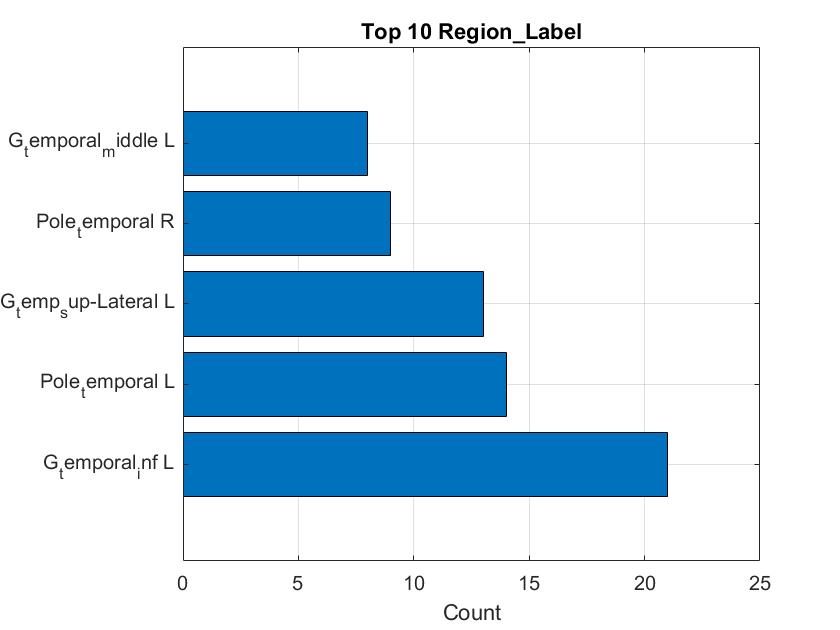

% Set full file path
filename = fullfile(folder_path, "region_table_spike.txt");

% Write the table to CSV
writetable(region_table_spike, filename);


%% Plotting the top 10 from each category
figure;
barh(region_table_spike.Count(1:5));
set(gca, 'yticklabel', region_table_spike.Region(1:5));
xlabel('Count');
title('Top 10 Region\_Label');
grid on;

Latex table


% Define folder and LaTeX filename
%folder_path = fullfile(getenv('USERPROFILE'), 'Documents\CSIC\navidad\patientMCC\arraysFT7'); % Windows
latex_filename = fullfile(folder_path, 'SOZ_Spike_Latex.tex');

% Open file for writing
fid = fopen(latex_filename, 'w');

% Write LaTeX table header
fprintf(fid, '\\begin{longtable}{|c|p{6cm}|}\n');
fprintf(fid, '\\hline\n');
fprintf(fid, '\\Spike & Brain Region \\\\\n');
fprintf(fid, '\\hline\n');
fprintf(fid, '\\endfirsthead\n');

fprintf(fid, '\\hline\n');
fprintf(fid, 'Spike & Brain Region \\\\\n');
fprintf(fid, '\\hline\n');
fprintf(fid, '\\endhead\n');

fprintf(fid, '\\hline\n');
fprintf(fid, '\\multicolumn{2}{r}{\\textit{Continued on next page}} \\\\\n');
fprintf(fid, '\\hline\n');
fprintf(fid, '\\endfoot\n');
fprintf(fid, '\\hline\n');
fprintf(fid, '\\caption{SOZ location determined by the Maximum of the Spikes} \\label{tab:eigenvalues} \\\\\n');
fprintf(fid, '\\endlastfoot\n');


if cont_spikes ~= 0
    for i = 1:size(all_spikes,1)
        region_cell = SOZ_struct_spike(i).Region_Labels;
        side_cell  = SOZ_struct_spike(i).Region_Sides;
        
            if iscell(region_cell) && iscell(side_cell)
                n_lines = length(region_cell);
                combined_lines = cell(1, n_lines);
                
                for k = 1:n_lines
                    reg = strrep(region_cell{k}, '_', '\_');
                    sid = strrep(side_cell{k}, '_', '\_');
                    % Combine each region and side into one line
                    combined_lines{k} = sprintf('%s \\hfill %s', reg, sid);  % use \hfill for alignment
                end
                
                region = strjoin(combined_lines, ' \\newline ');
                side = '';  % Leave side column empty since included in region
            else
                region = strrep(region_cell, '_', '\_');
                side = strrep(side_cell, '_', '\_');
            end
    
    
        % Write the table row
        fprintf(fid, '%d & %s  \\\\\n', ...
                    i, region);
    end
end

% Close table
fprintf(fid, '\\end{longtable}\n');

fclose(fid);
disp(['LaTeX table saved to ', latex_filename]);

LaTeX table saved to C:\Users\34651\Documents\CSIC\navidad\patientRMC\SOZ_Spike_Latex.tex
